# **Implementation of Video Compression (H.264)**

# **H.264:**

## Part 1) Low Compression

## A) Video Encoder 

            1) Reading the video and specifiying the I and P frames. 

            2) JPEG Encoding of the I-frame. 

                 a. Reading the image and check that it can be divided to an integer number of 8x8 blocks 

                 b. Divide the image into 8x8 Blocks on which DCT is applied 

                 c. DCT 8x8 Blocks are divided by a Low Quantization Table 

                 d. 8x8 Blocks are converted to 1-D vector (1x64) in a Serpentine pattern. 

                 e. Run Length Code is applied on the 1-D vectors 

                 f. Huffman Ecoding is applied on the Run Length Encoded Vectors

            3) Motion Estimation of the P-frames.  

            4) Motion Compensation of the P-frames.  

            5) JPEG Encoding of the P-frames.   

            6) Entropy Coding of the bitstream and the motion vectors.  

            7) Compression Ratio is Calculated.  

## B) Video Decoder 

            1) JPEG Decoding of the I-frame. 

                 a. Huffman Decoding is applied on the recieved vector   

                 b. Run Length Decoding is applied on the restored symbols 

                 c. Decoded Vector is divided into (1x64) blocks and then each bloch is converted to 2D 

                 d. Each 8x8 Block is multiplied by the Low Quantization Table 

                 e. IDCT is applied on the 8x8 Blocks 

                 f. Combine 8x8 pixel groups into a single image and construct the frame.

            2) Entropy Decoding of the motion vectors of macro blocks. 

            3) Reconstruct the macro blocks to produce the decoded frames. 

## C) Evaluation Test 

## Part 2) High Compression 

## Part 3) Arithmetic Coding 

### **Part 1) Low Compression**

#### **A) Video Encoder **

**1) Reading the video and specifiying the I and P frames. **

- The image is read using VideoReader() funciton.

- Columns and Rows of the Image are divided by 8 in order to check if they are divisible by 8 or not.

- If the Image can't be divided into an integer number of 8x8 block, rows and columns of zeros will be added to the image.

- The added zeros will be removed while reconstructing the image after decoding.

**2) JPEG Encoding of the I-frame. **

      **a) Reading the frame and check that it can be divided to an integer number of 8x8 blocks **

- The estimation is be based on one frame (previous I-frame or P-frame)

- The first frame is chosen to be I-frame, while the other frames are the P-frames.

- pad() function is used to ensure that frames can be divided to an integer number of 8x8 block.

- Columns and Rows of the frame are divided by 8 in order to check if they are divisible by 8 or not.

- If the frame can't be divided into an integer number of 8x8 block, rows and columns of zeros will be added to the frame.

- The added zeros will be removed while reconstructing the frame after decoding.

       **b) Divide the I-frame into 8x8 Blocks on which DCT is applied **

- DCT() Function is used to compute the DCT of 8x8 Blocks.

- Firstly, Basis Functions are comupted

- Secondly, each pixel is multiplied to the corresponding basis block and averaging them 

- Finally, the DCT Result is scaled such that:

               a) The first value in the block is divided by 64

               b) The first row is divided by 32

               c) The first column is divided by 32

               d) The rest of the block is divided by 16

       **c) DCT 8x8 Blocks are divided by a Low Quantization Table**  

- QuantizationTable() Function is used to find the Quantization Table.

- The function has 2 Tables for Low and High Compression.

- The Low Compression Table is used and the DCT 8x8 Block are divided by the Quantization Table

- After Division, the results are rounded to the nearest integer value.

       **d) 8x8 Blocks are converted to 1-D vector (1x64) **  

- serpentine(coded_vec) Function is used to convert from 2-D to 1-D.

- This function coverts the 8x8 2-D Block into 1x64 1-D Block as shown:

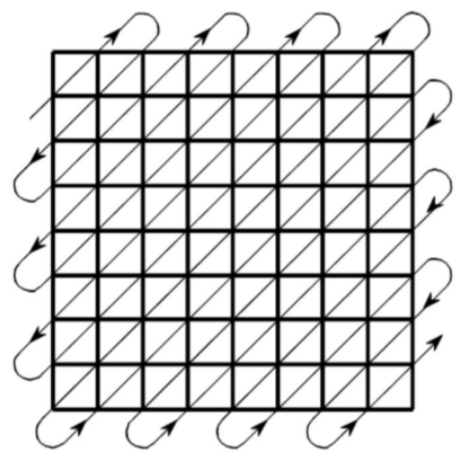

       **e) Run Length Code is applied on the 1-D vectors** 

- run_length() Function is used to compute the Run Length Code of a given 1x64 block.

- Since there are many zeros in the block, this will reduce the size in a lossless way.

- The function loops over the block and append the values while counting the number of zeros.

- It places only one zero followed by the count of the consecutive zeros.

       **f) Huffman Ecoding is applied on the Run Length Encoded Vectors **

- GetHuffmanCodes() function is used to compute the Huffman code of the blocks.

- Firstly, the unique symbols are found and their probabilities are computed using the frequency.

- Huffman Dictionary is obtained.

- Huffman_Encoder() function is used to find the encoded sequence.

**3) Motion Estimation of the P-frames.**

- Motion estimation is used to determine the movement of blocks of pixels between frames in order to accurately encode the differences between P-frames.

- The  motion_estimation function takes in the I and P frames, and returns an array image_motion_vector containing the motion vectors for each block of pixels in the image P.

- It compares blocks of pixels in the reference frame I to blocks of pixels in the current frame P, and determines the motion vectors for each block in P by finding the best match in the search area around the block. The motion vectors are then used to encode the differences between the frames I and P into a P-frame.

**4) Motion Compensation of the P-frames.**

- Motion compensation is a process that is used to reconstruct the current frame from the reference frame and the motion vectors that were determined during motion estimation.

- The motion_compensation function takes in an I frame, a predictive frame P, and an array image_motion_vector containing the motion vectors for the macro blocks in the P frame, and returns a diff_frame containing the differences between the frames I and P.

- The code then calls the encod_jpeg function to encode the I frame using JPEG encoding. This encoding step is included to compensate for errors that may occur at the decoder, as JPEG encoding is lossy and may introduce some distortion into the frame. The code then calls the decode_jpeg function to decode the encoded I frame back into a reconstructed frame I_recon. 

**5) JPEG Encoding of the P-frame. **

- P-frames encoding is performed using the same approach of I-frame encoding as discussed in point 2.

**6) Entropy Coding of the bitstream and the motion vectors**

- Entropy coding is a process that is used to reduce the file size of the encoded video stream by removing statistical redundancy in the data. 

- Entropy coding is typically used after the motion estimation and motion compensation steps have been performed, and the differences between the reference frame and the current frame have been calculated. 

- Huffman Encoding is applied on the motion vectors of the whole P-frames.

- Firstly, the unique symbols are found and their probabilities are computed using the frequency.

- Huffman Dictionary is obtained.

- Huffman_Encoder() function is used to find the encoded sequence.

clear;
close all;
clc;

% 1) Reading the video and specifiying the I and P frames.
% Video Reading 
v = VideoReader('xylophone.mp4');
index = 0;  %index of the frame
total_img_motion_vec = [];  %temp arr to hold the motion vectors of macro blocks.
total_frames = [];  %temp arr to hold pixels values of the whole video

%Saving the video in greyscale to compare it with the compressed video.
videoFReader = vision.VideoFileReader('xylophone.mp4');
videoFWriter = vision.VideoFileWriter('xylophone_gray.avi',...
   'FrameRate',videoFReader.info.VideoFrameRate);
while ~isDone(videoFReader)
   videoFrame = step(videoFReader);
   step(videoFWriter, rgb2gray(videoFrame));
end
release(videoFReader);
release(videoFWriter);


This is the I frame


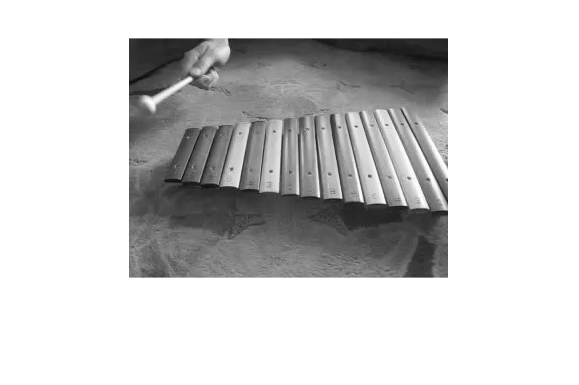

This is the P frame


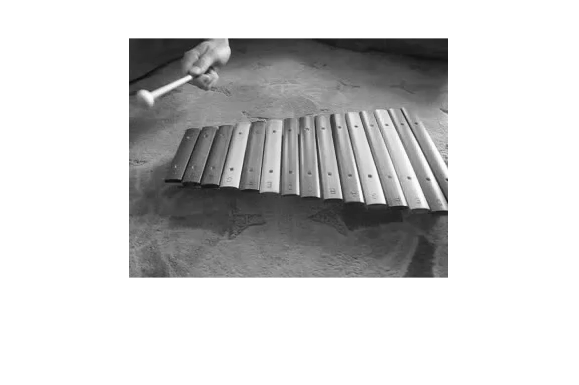

This is the difference frame


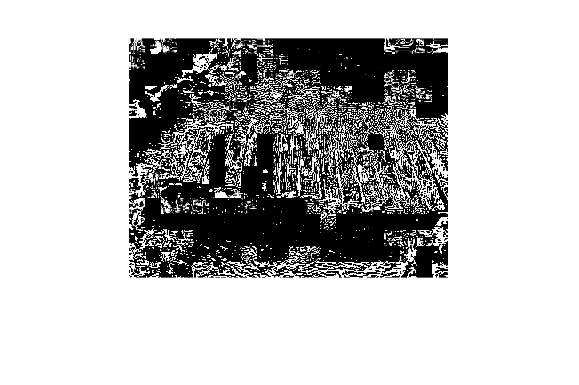

%Looping over the video frames
macro_block_size = 16;
while(hasFrame(v))
    frame = readFrame(v);  %reading the frame
    frame_gray = rgb2gray(frame);  %converting rgb frame to gray
    
    % Pad the image if required
    
    [R_img,C_img] = size(frame_gray); % to keep the size of the original image
    
    frame_gray = pad(frame_gray,macro_block_size);   % check inside the function if the size
    %of the image is divisable by macro_block_size, otherwise pad
    [R,C] = size(frame_gray);
    
    index = index + 1;
    %Specifiying the I-frame
    if index == 1
        disp('This is the I frame');
        figure();
        imshow(frame_gray);
        I = frame_gray;
        % 2) JPEG Encoding of the I-frame. 
        [out_jpeg] = encode_jpeg(I, 1);
        % JPEG encoding for I frame without entropy as 
        % it would be perfromed for the whole vedio at the and 
        
    else
        %Specifiying the P-frame
        % 3) Motion Estimation of the P-frames.
        [image_motion_vector] = motion_estimation(I,frame_gray);
        
        % 4) Motion Compensation of the P-frames.
        [diff_frame] = motion_compensation(I,frame_gray,image_motion_vector, 1);
        
        if(index == 2)
            disp('This is the P frame');
            figure();
            imshow(frame_gray);
            disp('This is the difference frame');
            figure();
            imshow(diff_frame);
        end
        
        % 5) JPEG Encoding of the P-frame. 
        [out_jpeg] = encode_jpeg(diff_frame, 1);
        
        % add -1 as a seperator between vectors of images cause it would never appear as a
        % number in vector motion 
        total_img_motion_vec = [total_img_motion_vec image_motion_vector -1];
    end
    
    % add 1000 as a seperator betweeen image frames 
    total_frames = [total_frames out_jpeg 1000];
    pause(2/v.FrameRate);
end


% 6) Entropy Coding of the bitstream and the motion vectors
[encoded_file,dict] = Huffman_Encoder(total_frames);  %Huffman Encoder of I and P frames
[img_motion_encoded_file,img_motion_dict] = Huffman_Encoder(total_img_motion_vec);  %Huffman Encoder of motion vectors


**7) Compression Ratio is Calculated**

- Compression Ratio is computed by dividing the original number of bits by the number of Huffman Bits of frames and motion vectors.

- Original Bits = 8 BitsPerPixel * NumFrames * Height * Width 

- Huffman Bits = Length of the Huffman Encoded Message of both frames and motion vectors.

% 7. Compression Ratio is Calculated  
num_bits_before_compression = (v.BitsPerPixel/3) * v.NumFrames * v.Height * v.Width;
num_bits_after_compression = length(encoded_file) + length(img_motion_encoded_file);
CR = num_bits_before_compression / num_bits_after_compression;
fprintf("The Compression Ratio is %f \n  ", CR);

The Compression Ratio is 3.559463 
  

#### **B) Video Decoder**

**1) JPEG Decoding of the I-frame.**

      **a. Huffman Decoding is applied on the recieved vector **

- HuffmanDecoder() function uses the dictionary and the encoded message to decode it.

      **b. Run Length Decoding is applied on the restored symbols** 

- run_length_decoder() Function is used to compute the Run Length Code of a given 1x64 block.

- The function finds the zeros and expands them using the count values which are placed after each zero.

      **c. Decoded Vector is divided into (1x64) blocks and then each bloch is converted to 2D**

- reverse_serpentine() Function is used to covert the 1x64 1-D Block into 8x8 2-D Block

      **d. Each 8x8 Block is multiplied by the Low Quantization Table** 

- QuantizationTable() Function is used to find the Quantization Table.

- The function has 2 Tables for Low and High Compression.

- The Low Compression Table is used and the 8x8 Blocks are multiplied by the Quantization Table

      **e. IDCT is applied on the 8x8 Blocks** 

- IDCT() Function is used to compute the IDCT of 8x8 Blocks.

- Firstly, Basis Functions are comupted

- A Loop over the size of the basis and size of the input is made.

- Multiplying each pixel to the corresponding basis block and averaging them then storing in dct_result.

      **f. Combine 8x8 pixel groups into a single image and construct the frame**   

- The image is reconstructed and the added zeros are removed.

- Values are converted into uint8.

**2) Entropy Decoding of the motion vectors of macro blocks.**

- HuffmanDecoder() function uses the dictionary and the encoded message to decode it.

- Since the motion vectors of each frame is separated by -1, the loctions of -1s are found using find function to find vectors of each P-frame

**2) Reconstruct the macro blocks to produce the decoded frames.**

- motion_reconstruction() function uses the I, diff_frame , and image_motion_vector to find the decoded P frames.

- The constructed motion vectors for a specific frame is passed to the function along with the constructed I and difference frames.

This is the received I frame


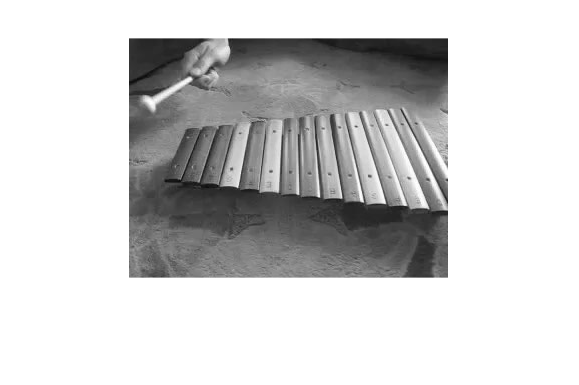

This is the P frame


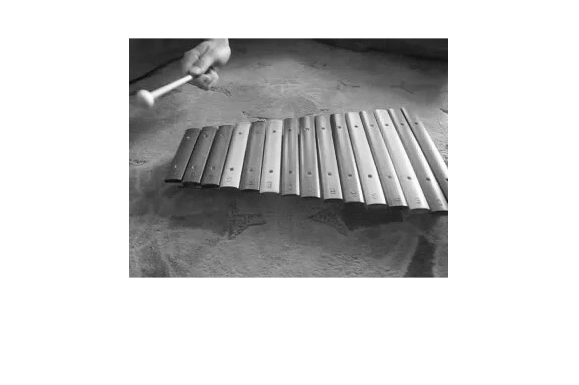

%Entropy Decoding of the motion vectors
img_motion_decode_file = Huffman_Decoder(img_motion_encoded_file,img_motion_dict);

%Entropy Decoding of the frames
frames_decode_file = Huffman_Decoder(encoded_file,dict);

%Video file to write the reconstructed_video
s = VideoWriter('reconstructed_video_Low.avi');  
open(s);

%Get the positions of the seperators 
frame_stop = find(frames_decode_file == 1000);
img_motion_stop = find(img_motion_decode_file == -1);

c=1;
start=1;
for i=1:length(frame_stop)
    if i == 1
        % use seperator positions to reconstruct frames 
        I_rec = frames_decode_file(1:frame_stop(i)-1);
        I_decoded=decode_jpeg(I_rec, R, C, 1);
        frame = I_decoded;
        disp('This is the received I frame');
        figure();
        imshow(uint8(I_decoded));
    else
        %Difference Frame
        diff_frame_rec = frames_decode_file(frame_stop(i-1)+1:frame_stop(i)-1);
        %Decoded Difference Frame
        diff_frame_decoded=decode_jpeg(diff_frame_rec, R, C, 1);
        image_motion_vector_rec = img_motion_decode_file(start:img_motion_stop(c)-1);
        c=c+1;
        start = img_motion_stop(c-1)+1;
        %P-frame Reconstruction 
        p = motion_reconstruction(I_decoded, diff_frame_decoded , image_motion_vector_rec);
        frame = p;
        if(i == 2)
            disp('This is the P frame');
            figure();
            imshow(uint8(frame));
        end
    end
    frame= frame(1:R_img, 1:C_img);
    frame = uint8(frame);
    writeVideo(s,frame);
end

close(s);


- **Comment:**

**Using Low Compression retains the quality of the video and it is clear even the compression ratio is 3.55**

#### **C) Evaluation Test **

- For the Subjective evaluation, each team member has watched carefully both the original and compressed videos and decided his/her Mean Opinion Score based on the following criteria 

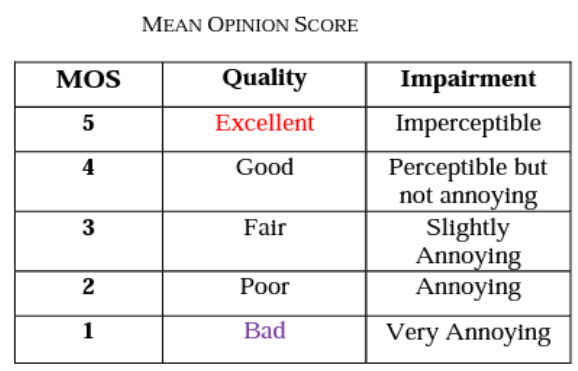

- The **following table** shows the scores for each team member:

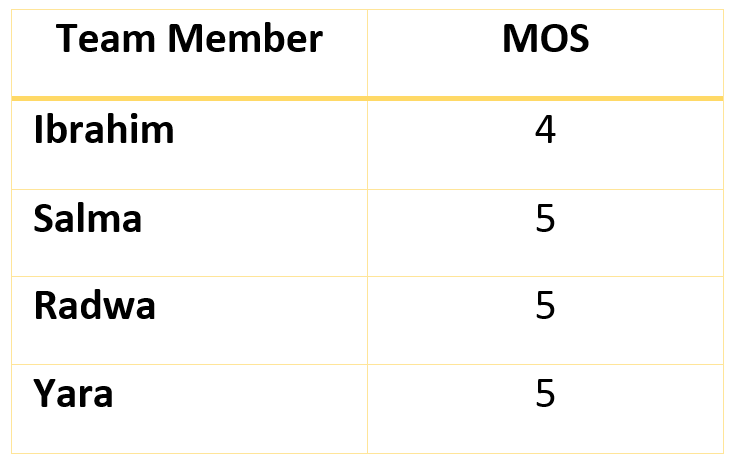

### **Part 2) High Compression**

**A) Video Encoder**

This is the I frame


This is the P frame


This is the difference frame


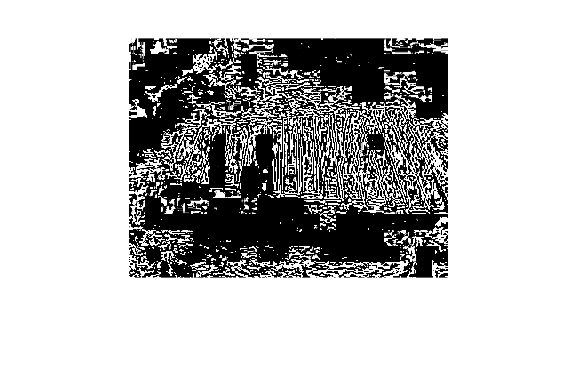

clear;
% 1) Reading the video and specifiying the I and P frames.
% Video Reading 
v = VideoReader('xylophone.mp4');
index = 0;  %index of the frame
total_img_motion_vec = [];  %temp arr to hold the motion vectors of macro blocks.
total_frames = [];  %temp arr to hold pixels values of the whole video

%Looping over the video frames
macro_block_size = 16;
while(hasFrame(v))
    frame = readFrame(v);  %reading the frame
    frame_gray = rgb2gray(frame);  %converting rgb frame to gray
    
     % Pad the image if required
    
    [R_img,C_img] = size(frame_gray); % to keep the size of the original image
    
    frame_gray = pad(frame_gray,macro_block_size);   % check inside the function if the size
    %of the image is divisable by macro_block_size, otherwise pad
    [R,C] = size(frame_gray);

    index = index + 1;
    %Specifiying the I-frame
    if index == 1
        disp('This is the I frame');
        figure();
        imshow(frame_gray);
        I = frame_gray;
        % 2) JPEG Encoding of the I-frame. 
        [out_jpeg] = encode_jpeg(I, 2);
        % JPEG encoding for I frame without entropy as 
        % it would be perfromed for the whole vedio at the and 
        
    else
        %Specifiying the P-frame
        % 3) Motion Estimation of the P-frames.
        [image_motion_vector] = motion_estimation(I,frame_gray);
        
        % 4) Motion Compensation of the P-frames.
        [diff_frame] = motion_compensation(I,frame_gray,image_motion_vector, 2);
        
        if(index == 2)
            disp('This is the P frame');
            figure();
            imshow(frame_gray);
            disp('This is the difference frame');
            figure();
            imshow(diff_frame);
        end
        
        % 5) JPEG Encoding of the P-frame. 
        [out_jpeg] = encode_jpeg(diff_frame, 2);
        
        % add -1 as a seperator between vectors of images cause it would never appear as a
        % number in vector motion 
        total_img_motion_vec = [total_img_motion_vec image_motion_vector -1];
    end
    
    % add 1000 as a seperator betweeen image frames 
    total_frames = [total_frames out_jpeg 1000];
    pause(2/v.FrameRate);
end


% 6) Entropy Coding of the bitstream and the motion vectors
[encoded_file,dict] = Huffman_Encoder(total_frames);  %Huffman Encoder of I and P frames
[img_motion_encoded_file,img_motion_dict] = Huffman_Encoder(total_img_motion_vec);  %Huffman Encoder of motion vectors

% 7. Compression Ratio is Calculated  
num_bits_before_compression = (v.BitsPerPixel/3) * v.NumFrames * v.Height * v.Width;
num_bits_after_compression = length(encoded_file) + length(img_motion_encoded_file);
CR = num_bits_before_compression / num_bits_after_compression;
fprintf("The Compression Ratio is %f \n  ", CR);

The Compression Ratio is 10.612334 
  

**B) Video Decoder**

This is the received I frame


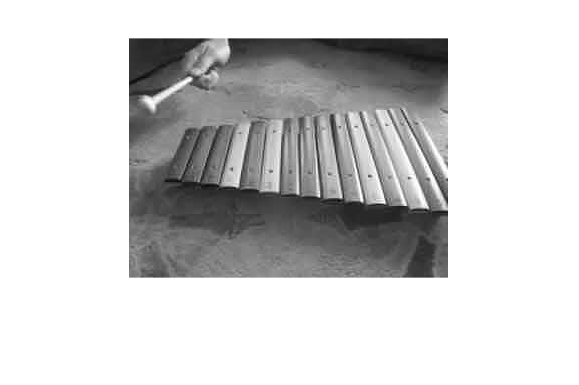

This is the P frame


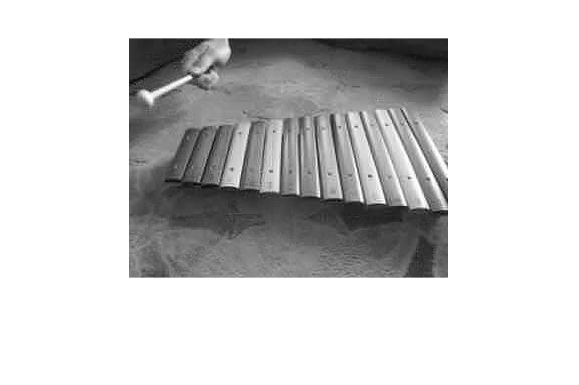

%Entropy Decoding of the motion vectors
img_motion_decode_file = Huffman_Decoder(img_motion_encoded_file,img_motion_dict);

%Entropy Decoding of the frames
frames_decode_file = Huffman_Decoder(encoded_file,dict);

%Video file to write the reconstructed_video
s = VideoWriter('reconstructed_video_High.avi');  
open(s);

%Get the positions of the seperators 
frame_stop = find(frames_decode_file == 1000);
img_motion_stop = find(img_motion_decode_file == -1);

c=1;
start=1;
for i=1:length(frame_stop)
    if i == 1
        % use seperator positions to reconstruct frames 
        I_rec = frames_decode_file(1:frame_stop(i)-1);
        I_decoded=decode_jpeg(I_rec, R, C, 2);
        frame = I_decoded;
        disp('This is the received I frame');
        figure();
        imshow(uint8(I_decoded));
    else
        %Difference Frame
        diff_frame_rec = frames_decode_file(frame_stop(i-1)+1:frame_stop(i)-1);
        %Decoded Difference Frame
        diff_frame_decoded=decode_jpeg(diff_frame_rec, R, C, 2);
        image_motion_vector_rec = img_motion_decode_file(start:img_motion_stop(c)-1);
        c=c+1;
        start = img_motion_stop(c-1)+1;
        %P-frame Reconstruction 
        p = motion_reconstruction(I_decoded, diff_frame_decoded , image_motion_vector_rec);
        frame = p;
        if(i == 2)
            disp('This is the P frame');
            figure();
            imshow(uint8(frame));
        end
    end
    frame = uint8(frame);
    writeVideo(s,frame);
end

close(s);


- **Comment:**

**Using High Compression lead to a very low quality version of the video and however its main features are still clear even the compression ratio is 10.61**

#### **C) Evaluation Test **

- For the Subjective evaluation, each team member has watched carefully both the original and compressed videos and decided his/her Mean Opinion Score based on the following criteria 

- The **following table** shows the scores for each team member:

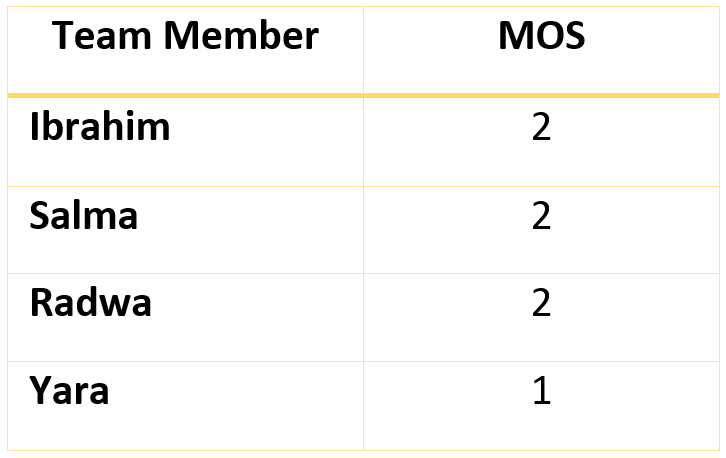

### **Part 3) Arithmetic Coding**

- **In the Bonus task, we had tried to use our implementend function of the arithmetic coding (encoder and decoder). The function is working right but there is a problem scince the total number of frames is large enough so the function will take a huge time to encode the input data.**

- **One of the trial to optimize the code in order to minimize the time is to divie the total frames into parts and take smaller number of sequence then encode each part on its own, but still that would take much time to finish. **

- **So here, you can find the final update of our implemented function as code without results.**

**A) Video Encoder**

This is the I frame


This is the P frame


This is the difference frame


clear;
% 1) Reading the video and specifiying the I and P frames.
% Video Reading 
v = VideoReader('xylophone.mp4');
index = 0;  %index of the frame
total_img_motion_vec = [];  %temp arr to hold the motion vectors of macro blocks.
total_frames = [];  %temp arr to hold pixels values of the whole video

%Looping over the video frames
macro_block_size = 16;
for f_num = 1:2
    frame = readFrame(v);  %reading the frame
    frame_gray = rgb2gray(frame);  %converting rgb frame to gray
    
     % Pad the image if required
    
    [R_img,C_img] = size(frame_gray); % to keep the size of the original image
    
    frame_gray = pad(frame_gray,macro_block_size);   % check inside the function if the size
    %of the image is divisable by macro_block_size, otherwise pad
    [R,C] = size(frame_gray);

    index = index + 1;
    %Specifiying the I-frame
    if index == 1
        disp('This is the I frame');
        figure();
        imshow(frame_gray);
        I = frame_gray;
        % 2) JPEG Encoding of the I-frame. 
        [out_jpeg] = encode_jpeg(I, 2);
        % JPEG encoding for I frame without entropy as 
        % it would be perfromed for the whole vedio at the and 
        
    else
        %Specifiying the P-frame
        % 3) Motion Estimation of the P-frames.
        [image_motion_vector] = motion_estimation(I,frame_gray);
        
        % 4) Motion Compensation of the P-frames.
        [diff_frame] = motion_compensation(I,frame_gray,image_motion_vector, 2);
        
        if(index == 2)
            disp('This is the P frame');
            figure();
            imshow(frame_gray);
            disp('This is the difference frame');
            figure();
            imshow(diff_frame);
        end
        
        % 5) JPEG Encoding of the P-frame. 
        [out_jpeg] = encode_jpeg(diff_frame, 2);
        
        % add -1 as a seperator between vectors of images cause it would never appear as a
        % number in vector motion 
        total_img_motion_vec = [total_img_motion_vec image_motion_vector -1];
    end
    
    % add 1000 as a seperator betweeen image frames 
    total_frames = [total_frames out_jpeg 1000];
    pause(2/v.FrameRate);
end

% 6) Entropy Coding of the bitstream and the motion vectors
[encoded_file, prop_f, symbol_f] = arthencodewrap(total_frames);  %Huffman Encoder of I and P frames
[img_motion_encoded_file, prop_v, symbol_v] = arthencodewrap(total_img_motion_vec);  %Huffman Encoder of motion vectors

% 7. Compression Ratio is Calculated  
num_bits_before_compression = 8 * 2 * v.Height * v.Width;
num_bits_after_compression = length(encoded_file) + length(img_motion_encoded_file);
CR = num_bits_before_compression / num_bits_after_compression;
fprintf("The Compression Ratio is %f \n  ", CR);

**B) Video Decoder**

%Entropy Decoding of the motion vectors
img_motion_decode_file = arthdecoderwrapper(img_motion_encoded_file, prop_f, symbol_f);

%Entropy Decoding of the frames
frames_decode_file = arthdecoderwrapper(encoded_file, prop_v, symbol_v);

%Video file to write the reconstructed_video
s = VideoWriter('reconstructed_video_High_Arith.avi');  
open(s);

%Get the positions of the seperators 
frame_stop = find(frames_decode_file == 1000);
img_motion_stop = find(img_motion_decode_file == -1);

c=1;
start=1;
for i=1:length(frame_stop)
    if i == 1
        % use seperator positions to reconstruct frames 
        I_rec = frames_decode_file(1:frame_stop(i)-1);
        I_decoded=decode_jpeg(I_rec, R, C, 2);
        frame = I_decoded;
        disp('This is the received I frame');
        figure();
        imshow(uint8(I_decoded));
    else
        %Difference Frame
        diff_frame_rec = frames_decode_file(frame_stop(i-1)+1:frame_stop(i)-1);
        %Decoded Difference Frame
        diff_frame_decoded=decode_jpeg(diff_frame_rec, R, C, 2);
        image_motion_vector_rec = img_motion_decode_file(start:img_motion_stop(c)-1);
        c=c+1;
        start = img_motion_stop(c-1)+1;
        %P-frame Reconstruction 
        p = motion_reconstruction(I_decoded, diff_frame_decoded , image_motion_vector_rec);
        frame = p;
        if(i == 2)
            disp('This is the P frame');
            figure();
            imshow(uint8(frame));
        end
    end
    frame = uint8(frame);
    writeVideo(s,frame);
end
close(s);